# Channel Estimation for Passive RIS - Convetional Approach

**Author:** Roberto Câmara (camara2k@gmail.com/ camara@ime.eb.br)

**Start Date:** 

### Introduction to the Code: 

Channel Estimation for Intelligent Reflecting Surface Assisted Multiuser Communications: Framework, Algorithms, and Analysis.

#### Phase 1

Without noise:

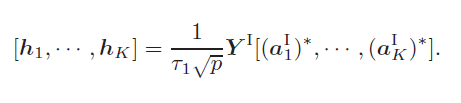

With noise:

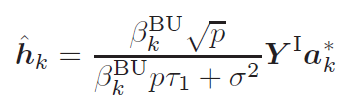

#### Phase 2

Without noise:

 

With noise:

 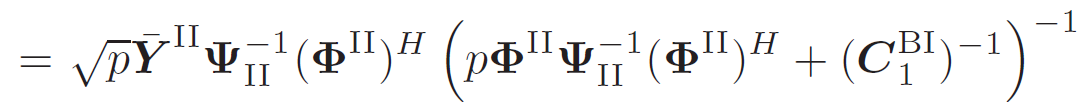

### Numerical Results of the Code: 

### Basic Variables:

function channel = CE_PRIS_CONV(sys, channel, estimation, noise_LOS, noise_NLOS, pwr)
    
    % Selection if the noise is 
    switch lower(noise_LOS)
        case 'with_noise'
    wo_los_noise = 1;
        case 'without_noise'
    wo_los_noise = 0;
        otherwise
            error('Method not listed: %s', noise_mode);
    end

    % Selection if the noise is 
    switch lower(noise_NLOS)
        case 'with_noise'
    wo_nlos_noise = 1;
        case 'without_noise'
    wo_nlos_noise = 0;
        otherwise
            error('Method not listed: %s', noise_mode);
    end

    % For the conventional approach, the estimation is divided in two phases
    pilotsLenght_0 = estimation.T0_min;
    % pilots_0 = estimation.pilots;
    pilotsLenght_1 = estimation.T1_min;

    % Power Normalization -----------------------------------
    % It is based on the noise of estimation var
    sigma2_nest = (10^(estimation.noise_dbm/10));
    sigma2_s = sys.PWR(pwr);
    
    %% ===============Phase I===========================
    F0_temp=dftmtx(pilotsLenght_0);
    pilots = F0_temp(1:sys.n_tx,:)*sqrt(sigma2_s); % pilots
    pilotsH = pilots';
    
    noise = sqrt(sigma2_nest/2)*(randn(sys.n_rx,pilotsLenght_0)+1j*randn(sys.n_rx,pilotsLenght_0));
    Y0 = channel.H*pilots+noise;
    
    if wo_los_noise
        %% With noise --------------------------------------
        A = inv(pilotsH*diag(channel.Hkloss)*pilots + sigma2_nest*eye(pilotsLenght_0))*pilotsH*diag(channel.Hkloss);
        H_est = Y0*A;
   
    else
        %% Without noise -----------------------------------
        factor = 1/(pilotsLenght_0*sqrt(sigma2_s));
        H_est = factor*Y0*pilotsH;
    end

%% ===============Phase II===========================
    F1=dftmtx(pilotsLenght_1);
    Phi1 = F1(1:sys.Nc,:); % pilots
    pilots = ones(1,pilotsLenght_1)*sqrt(sigma2_s);
    noise = sqrt(sigma2_nest/2)*(randn(sys.n_rx,pilotsLenght_1)+1j*randn(sys.n_rx,pilotsLenght_1));

    if wo_nlos_noise
        %% With noise --------------------------------------
        factor2 = sigma2_s*sys.n_rx*channel.Hkloss*sigma2_nest./(channel.Hkloss*sigma2_s*pilotsLenght_1+sigma2_nest);
        Z_est = zeros(sys.n_rx,sys.Nc,sys.n_tx);
        for i = 1:sys.n_tx
            Y1 = channel.G*diag(channel.F(:,i))*Phi1*diag(pilots) + channel.H(:,i)*pilots + noise;
            Y1 = Y1 - H_est(:,i)*pilots;

            Psi_k = factor2(i)*ones(pilotsLenght_1)+sys.n_rx*sigma2_nest*eye(pilotsLenght_1);
            Psi_k_inv = Psi_k\eye(pilotsLenght_1);
            C_BI = channel.Zkloss(i)*eye(sys.Nc);
            C_BI_inv = C_BI*eye(sys.Nc)\eye(sys.Nc);
            Z_est(:,:,i) = sqrt(sigma2_s)*(Y1)*Psi_k_inv*Phi1'/(sigma2_s*Phi1*Psi_k_inv*Phi1'+ C_BI_inv);
        end
    else
        %% Without noise -----------------------------------
        factor = 1/(pilotsLenght_1*sqrt(sigma2_s));
        Z_est = zeros(sys.n_rx,sys.Nc,sys.n_tx);
        for i = 1:sys.n_tx
            Y1 = channel.G*diag(channel.F(:,i))*Phi1*diag(pilots) + channel.H(:,i)*pilots + noise;
            Y1_refl = Y1 - H_est(:,i)*pilots;

            Gf_est = factor*Y1_refl*Phi1';
            Z_est(:,:,i) = Gf_est;
        end
    end

    % output
    channel.H_est = H_est;
    channel.Z_est = Z_est;
end